#     MA 433 Optimization Final Project

by Dongwoo (Edward) Han and I-Le (Raymond) Wang

## Introduction

            The project the team chose to do was the glider project from **AE413 – Airplane Stability and Controls** taught by Dr. Bordignon with a mathematical approach. Unlike the procedures from AE413 where the students would guess inputs in attempt to discover an optimal design. the team will attempt to use the knowledge that was taught by Dr. Wall and use a numerical method to determine the optimal inputs which would lead to the optimal design of the aircraft, in other words, to maximize the distance the glider is able to travel. Once the optimal inputs have been determined the team will then input the result into Simulink which would simulate the performance of the glider.

            This document contains the approach the team attempted along with the equations used for the numerical method of solving this problem. Certain parameters and constraints were given due to the laws of nature and some were given by Dr. Bordignon which will be further discussed in **Design Constraints **and **Equations Used **sections. After defining the equations and parameters and constraints the team then proceeded with the determining the optimal input solution and will input the inputs into Simulink to determine that the glider design is optimal. 

            The document is written in a way that future readers can follow this document and replicate the project and to derive the same conclusion.

## Approach

The first thing the team determined was the cost function, in this case to maximize the distance the glider can travel. The range equation of a glider

                                             
$$C_L\frac1 2\rho_\infty V_\infty^2\over C_D\frac1 2\rho_\infty V_\infty^2$$
 

 Where the dynamic pressure and area will cancel out resulting with a simplified version of the range equation  $C_L\over C_D$ which will be the cost function the team will attempt to optimize.  

After determining the cost function that the team will attempt to maximize. The team then determined the equations that were needed to determine   the equations was provided to us during AE413 which the team translated the equations into MatLab codes.

## Design Constraints

(Given by Dr. Bordignon in the instruction paper of the AE 413 Glider Project)

- Wing span 18” or less:           $b \le 18 \text{ inches}$ $b_H \le 18 \text{ inches}$ $b \le 18 \text{ inches}$

- Fuselage Length 18” or less

- Chord 3” or less for all lifting surfaces: $c_R \le 3 \text{ inches}$ $c_T \le 3 \text{ inches}$ ${c_R}_V  \le 3 \text{ inches}$ ${c_T}_V  \le 3 \text{ inches}$ ${c_R}_H  \le 3 \text{ inches}$ ${c_T}_H  \le 3 \text{ inches}$ 

- Total mass shall not exceed 0.11 lbs

- Ballast weight cannot exceed 0.025 lbs

- Conventional horizontal tail or canard design allowed

- Three recorded launches will be used to attain your graded distance

- Must utilized supplied balsawood or replacement of the same size

- Only straight tapered wings allowed

- All lifting surfaces must be within valid ranges of Polhamus Formula 

- Moderate sweep:        $\Lambda_{LE} < 30^\circ$ ${\Lambda_{LE}}_{H} < 30^\circ$ ${\Lambda_{LE}}_{V} < 30^\circ$

- Moderate Aspect Ratio is between 3 to 8:  $3< AR < 8$

- Moderately High Taper Ratio is between 0.4 to 1 $0.4 \le \lambda \le 1$ $0.4 \le \lambda_H \le 1$ $0.4 \le \lambda_V \le 1$

- All modes must be done be stable 

- No gimmicks unless approved by instructor

Material constraints: 

- 2 sheets for wing and tail surfaces: 36” X 3” X 3/32” each

- 2 Fuselage Sticks 3/16” X 1/2” X 36” each

- Balsa wood density ~ 0.00578 lbf/in^3

- Other approved materials: Rubber bands, glue, tape, modeling clay

Given parameters: 

- Air Density ($\rho_\infty$) = 0.002048 [slug/ft^3]

- Balsa Wood Density ($\rho_{balsa}$) =  0.0578 [lb(t)/in^3]

- Gravitational Acceleration ($g $) = 32.174 [ft/s^2]

- Speed of Sound ($a_\infty$) = 1096.869 [ft/s]

- 2-D lift slope coefficient (${c_l}_\alpha$) = 4.584 [1/rad]

- air_viscosity ($\mu_\infty$) =  0.0000003636 [lb(t)-s/ft^2]

- eta_VT ($\eta_V$) = 1

- eta_HT ($\eta_T$) = 1

- thickness = 3/32 [in]

clc;
clear;
close all;

a = 1096.86914442881; % ft/s, GIVEN
cl_alpha = 4.58366236104659; % 1/rad, GIVEN
density = 0.00578; % lb(t)f/in^3, GIVEN
air_density = 0.002048; % slug/ft^3, GIVEN
air_viscosity = 0.0000003636; %lb(t)-s/ft^2, GIVEN
gravity = 32.174;     % ft/s^2, GIVEN
eta_VT = 1;     % GIVEN
eta_HT = 1;     % GIVEN
thickness = 3/32; % GIVEN, thickness, 3/32 inches

## Equations Used

Equations shown below, which are all equations learned from AE 413: Airplane Stability and Controls, are used.

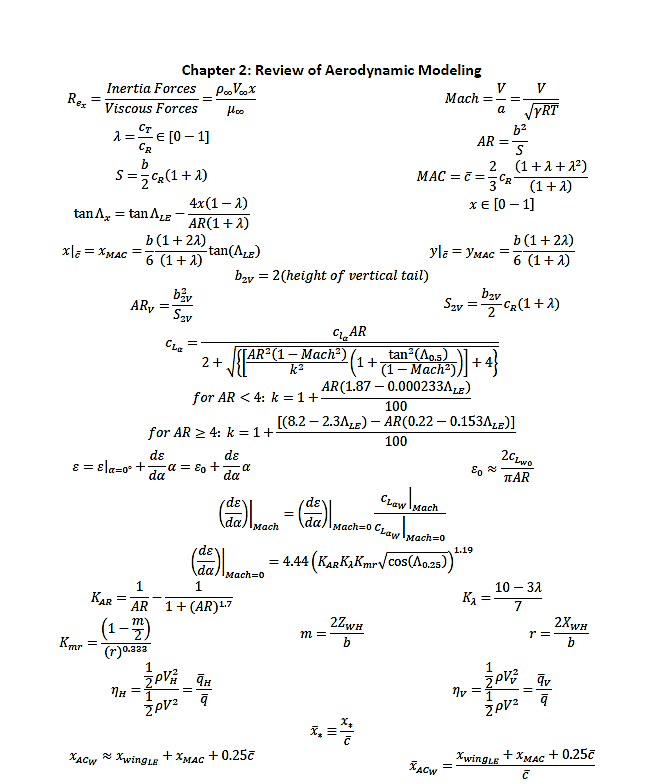

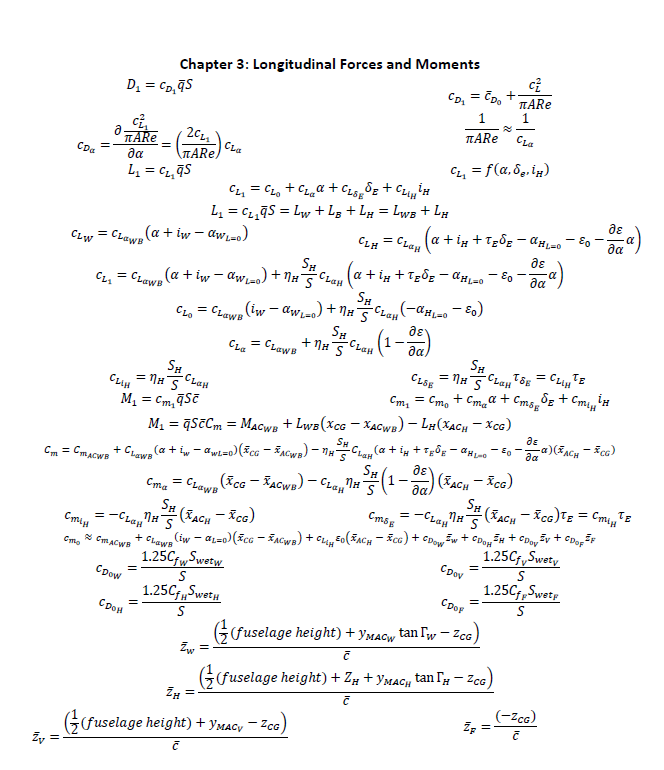

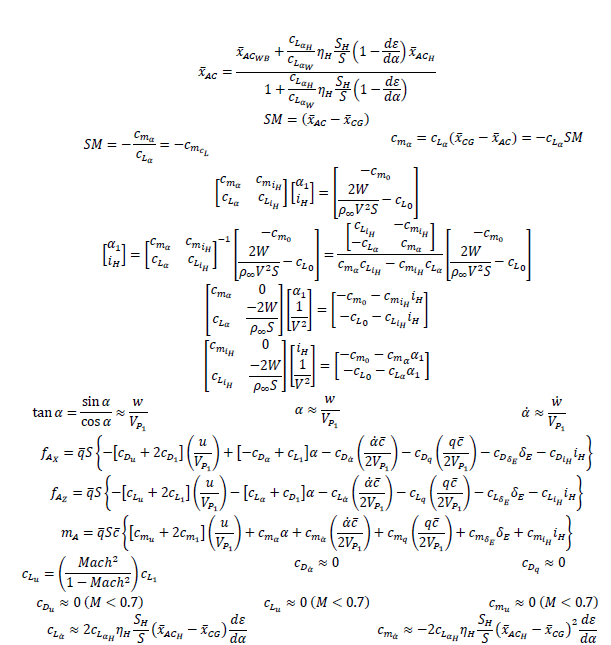

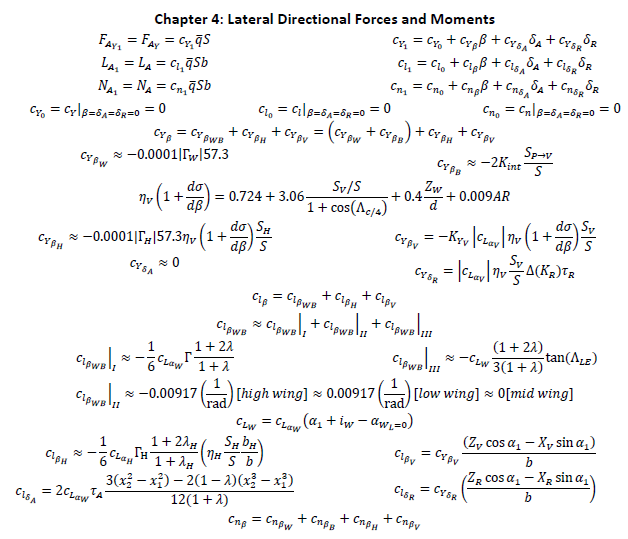

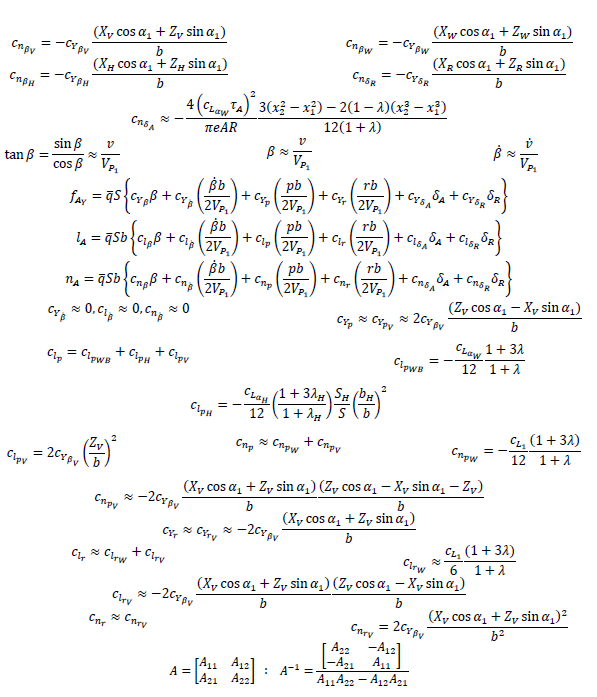

## Symbolic for Controls (Inputs)

syms V_trim(t) b(t) c_R(t) c_T(t) Gamma(t) LE_Sweep(t) i_W(t) x_wing_LE(t) ... % Wing Inputs
                                                   ... % Gamma(t) = Dihedral_Wing
     b_HT(t) c_R_HT(t) c_T_HT(t) Gamma_HT(t) Sweep_h_LE(t) x_HT_LE(t) z_HT(t)...  % HT Inputs
     VT_Height(t) c_R_VT(t) c_T_VT(t) Sweep_v_LE(t) x_VT_LE(t) ... %VT Inputs
     Fuselage_Length(t) Fuselage_Height(t) Fuselage_Width(t)... %Fuselage Length, Height, Width
     x_ballast(t) wt_ballast(t)... % ballast
     % End of Inputs

## Chapter 2 Symbolic Equations

Mach = V_trim(t)/a; % Should be constant

% Wing

lambda_Wing = c_T(t)/c_R(t);                    % Taper Ratio
S_Wing = (b(t)/2)*c_R(t)*(1+lambda_Wing);       % Surface Area
AR_Wing = (b(t)^2)/S_Wing;                      % Aspect Ratio
cbar = (2/3)*c_R(t)*((1+lambda_Wing+lambda_Wing^2)/(1+lambda_Wing)); % Mean Chord

% 0<x<1
% x_Sweep = atan(tan(LE_Sweep(t))-((4*x)*(1-lambda_Wing))/(AR_Wing*(1+lambda_Wing)));
HalfSweep = atan(tan(LE_Sweep(t))-((4*0.5)*(1-lambda_Wing))/(AR_Wing*(1+lambda_Wing))); % Half Sweep Angle
QuarterSweep = atan(tan(LE_Sweep(t))-((4*0.25)*(1-lambda_Wing))/(AR_Wing*(1+lambda_Wing))); % Quarter Sweep Angle
TE_Sweep = atan(tan(LE_Sweep(t))-((4*1)*(1-lambda_Wing))/(AR_Wing*(1+lambda_Wing)));     %Trailing Edge Sweep Angle

xmac_wing = ((b(t)*(1+2*lambda_Wing))/(6*(1+lambda_Wing)))*tan(LE_Sweep(t));             % X-Axis Mean Aerodynamic Center
ymac_wing = (b(t)*(1+2*lambda_Wing))/(6*(1+lambda_Wing));                                % Y-Axis Mean Aerodynamic Center

Re_wing = air_density*V_trim(t)*(cbar/12)/air_viscosity; % Reynold's Number
Cf_wing = 1.327/sqrt(Re_wing);                           % Coefficient of Friction

k = 1+((8.2-2.3*LE_Sweep(t))-AR_Wing*(0.22-0.153*LE_Sweep(t)))/100; % When Aspect Ratio is greater than 4.

Optimized value of cost function is found when aspect ratio is greater than 4. So equation of k above is used instead of equation of k when asepct ratio is below 4.


CL_alpha_Wing = (cl_alpha*AR_Wing)/(2+(sqrt(((AR_Wing^2*(1-Mach^2))/(k^2))*(1+(tan(HalfSweep)^2)/(1-Mach^2))+4))); % 3-D Lift Slope
K_AR = (1/AR_Wing)-(1)/(1+(AR_Wing^1.7));
K_lambda = (10-3*lambda_Wing)/7;

Z_WH = z_HT(t);
X_WH = (x_HT_LE(t) + 0.25*c_R_HT(t)) - (x_wing_LE(t) +0.25*c_R(t));

m = (2*Z_WH)/b(t);
r = (2*X_WH)/b(t);
K_mr = (1-(m/2))/(r^0.333);

WingArea = S_Wing/cos(Gamma(t));
wt_wing = WingArea*thickness*density;

xac_wing = x_wing_LE(t) + xmac_wing + 0.25*cbar;
xac_wing_bar = xac_wing/cbar;
xcg_wing = x_wing_LE(t) + xmac_wing + 0.5*cbar;

de_da_Mach0 = 4.44*(K_AR*K_lambda*K_mr*sqrt(cos(QuarterSweep)))^1.19;

CL_alpha_Mach0 = cl_alpha*AR_Wing/(2+sqrt((AR_Wing^2/k^2)*(1+tan(HalfSweep)^2)+4));
de_da = (de_da_Mach0)*(CL_alpha_Wing)/(CL_alpha_Mach0);
CL_Wing_0 = CL_alpha_Wing*i_W(t);
e0 = (2*CL_Wing_0)/(pi*AR_Wing);

% Horizontal Tail

lambda_HT = c_T_HT(t)/c_R_HT(t);
S_HT = (b_HT(t)/2)*c_R_HT(t)*(1+lambda_HT);
AR_HT = (b_HT(t)^2)/S_HT;
cbar_HT = (2/3)*c_R_HT(t)*((1+lambda_HT+lambda_HT^2)/(1+lambda_HT));

HTArea = S_HT/cos(Gamma_HT(t));
wt_HT = HTArea*thickness*density;

HalfSweep_h = atan(tan(Sweep_h_LE(t))-((4*0.5)*(1-lambda_HT))/(AR_HT*(1+lambda_HT)));
TE_Sweep_ht = atan(tan(Sweep_h_LE(t))-((4*1)*(1-lambda_HT))/(AR_HT*(1+lambda_HT)));

xmac_HT = ((b_HT(t)*(1+2*lambda_HT))/(6*(1+lambda_HT)))*tan(Sweep_h_LE(t));
ymac_HT = ((b_HT(t)*(1+2*lambda_HT))/(6*(1+lambda_HT)));
xac_HT = x_HT_LE(t) + xmac_HT + 0.25*cbar_HT;
xcg_HT = x_HT_LE(t) + xmac_HT + 0.5*cbar_HT;

Same as principle used for wing, optimal cost is found when aspect ratio of horizontal tail is greater than 4. So equation of k for horizontal tail above is used instead of equation of k when asepct ratio of horizontal tail is below 4.

k_HT = 1+((8.2-2.3*Sweep_h_LE(t))-AR_HT*(0.22-0.153*Sweep_h_LE(t)))/100; %AND TRY THIS
CL_alpha_HT = (cl_alpha*AR_HT)/(2+(sqrt(((AR_HT^2*(1-Mach^2))/(k_HT^2))*(1+(tan(HalfSweep_h)^2)/(1-Mach^2))+4)));

Re_H = air_density*V_trim(t)*(cbar_HT/12)/air_viscosity;
CfH = 1.328/sqrt(Re_H);
% CfH = 0.074/(Re_H^(1/5));

% Vertical Tail

b_VT = VT_Height(t); % Height of vertical tail 
b2v = 2*b_VT;
S_VT = (VT_Height(t)/2)*(c_R_VT(t)+c_T_VT(t)); % Surface Area of Vertical Tail
lambda_VT = c_T_VT(t)/c_R_VT(t);
S2v = (b2v/2)*c_R_VT(t)*(1+lambda_VT);
AR_VT = (b2v^2)/S2v;

wt_VT = S_VT*thickness*density;

cbar_VT = (2/3)*c_R_VT(t)*((1+lambda_VT+lambda_VT^2)/(1+lambda_VT));
HalfSweep_v = atan(tan(Sweep_v_LE(t))-((4*0.5)*(1-lambda_VT))/(AR_VT*(1+lambda_VT)));
TE_Sweep_vt = atan(tan(Sweep_v_LE(t))-((4*1)*(1-lambda_VT))/(AR_VT*(1+lambda_VT)));

xmac_VT = ((b2v*(1+2*lambda_VT))/(6*(1+lambda_VT)))*tan(Sweep_v_LE(t));
ymac_VT = ((b2v*(1+2*lambda_VT))/(6*(1+lambda_VT)));
xac_VT = x_VT_LE(t) + xmac_VT + 0.25*cbar_VT;
xcg_VT = x_VT_LE(t) + xmac_VT + 0.5*cbar_VT;


k_VT = 1+((8.2-2.3*Sweep_v_LE(t))-AR_VT*(0.22-0.153*Sweep_v_LE(t)))/100;

Same as principle used for wing, optimal cost is found when aspect ratio of vertical tail is greater than 4. So equation of k for vertical tail above is used instead of equation of k when asepct ratio of vertical tail is below 4.

CL_alpha_VT = (cl_alpha*AR_VT)/(2+(sqrt(((AR_VT^2*(1-Mach^2))/(k_VT^2))*(1+(tan(0.5*HalfSweep_v)^2)/(1-Mach^2))+4)));

Re_V = air_density*V_trim(t)*(cbar_VT/12)/air_viscosity;
CfV = 1.328/sqrt(Re_V);
% CfV = 0.074/(Re_V^(1/5));

% FUSELAGE

x_FS_CG = Fuselage_Length(t)/2;
wt_FS = Fuselage_Length(t)*Fuselage_Height(t)*Fuselage_Width(t)*density;

Re_fuse = air_density*V_trim(t)*(Fuselage_Length(t)/12)/air_viscosity;
Cffuse = 1.328/sqrt(Re_fuse);
% Cffuse = 0.074/(Re_fuse^(1/5)); %TRY THIS ONE TOO

## Mass Properties Symbolic Equations

Weight and mass of glider components (left and right wings, left and right horizontal tail, vertical tail, ballast, and fuselage) are found below.

wt_Rwing = wt_wing/2;
wt_Lwing = wt_wing/2;
wt_Rht = wt_HT/2;
wt_Lht = wt_HT/2;

mass_ballast = wt_ballast(t)/gravity;
mass_Rwing = wt_Rwing/gravity; 
mass_Lwing = wt_Lwing/gravity;
mass_Fuselage = wt_FS/gravity;
mass_Rht = wt_Rht/gravity;
mass_Lht = wt_Lht/gravity;
mass_Vt = wt_VT/gravity;
mass_all = mass_ballast + mass_Rwing + mass_Lwing + mass_Fuselage + mass_Rht + mass_Lht + mass_Vt;
Weight_all = mass_all*gravity;

Symbolic equations of center of gravity of glider components are found below.


Xc_ballast = x_ballast(t)/12;
Yc_ballast = 0;
Zc_ballast = 0;

Xc_Rwing = xcg_wing/12;
Yc_Rwing = ymac_wing/12;
Zc_Rwing = (0.5*(Fuselage_Height(t)) + ymac_wing*tan(Gamma(t)))/12;

Xc_Lwing = xcg_wing/12;
Yc_Lwing = -ymac_wing/12;
Zc_Lwing = (0.5*(Fuselage_Height(t)) + ymac_wing*tan(Gamma(t)))/12;

Xc_Fuselage = x_FS_CG/12;
Yc_Fuselage = 0;
Zc_Fuselage = 0;

Xc_Rht = xcg_HT/12;
Yc_Rht = ymac_HT/12;
Zc_Rht = (0.5*(Fuselage_Height(t)) + z_HT(t) + ymac_HT*tan(Gamma_HT(t)))/12;

Xc_Lht = xcg_HT/12;
Yc_Lht = -ymac_HT/12;
Zc_Lht = (0.5*(Fuselage_Height(t)) + z_HT(t) + ymac_HT*tan(Gamma_HT(t)))/12;

Xc_Vt = xcg_VT/12;
Yc_Vt = 0;
Zc_Vt = (0.5*Fuselage_Height(t) + ymac_VT)/12;

Symbolic equations of center of gravity (in x,y, and z axis) are found.

Xcg = ((Xc_ballast*mass_ballast)+(Xc_Rwing*mass_Rwing)+(Xc_Lwing*mass_Lwing)...
    +(Xc_Fuselage*mass_Fuselage)+(Xc_Rht*mass_Rht)+(Xc_Lht*mass_Lht)+(Xc_Vt*mass_Vt))/mass_all;
Ycg = ((Yc_ballast*mass_ballast)+(Yc_Rwing*mass_Rwing)+(Yc_Lwing*mass_Lwing)...
    +(Yc_Fuselage*mass_Fuselage)+(Yc_Rht*mass_Rht)+(Yc_Lht*mass_Lht)+(Yc_Vt*mass_Vt))/mass_all;
Zcg = ((Zc_ballast*mass_ballast)+(Zc_Rwing*mass_Rwing)+(Zc_Lwing*mass_Lwing)...
    +(Zc_Fuselage*mass_Fuselage)+(Zc_Rht*mass_Rht)+(Zc_Lht*mass_Lht)+(Zc_Vt*mass_Vt))/mass_all;

All symbolic equations for mass moment of inertia of glider components are found below.

Ixx_ballast(t) = ((Yc_ballast - Ycg)^2 + (Zc_ballast - Zcg)^2)*mass_ballast;
Iyy_ballast = ((Xc_ballast - Xcg)^2 + (Zc_ballast - Zcg)^2)*mass_ballast;
Izz_ballast = ((Xc_ballast - Xcg)^2 + (Yc_ballast - Ycg)^2)*mass_ballast;
Ixy_ballast = ((Xc_ballast - Xcg)*(Yc_ballast - Ycg))*mass_ballast;
Ixz_ballast = ((Xc_ballast - Xcg)*(Zc_ballast - Zcg))*mass_ballast;
Iyz_ballast = ((Yc_ballast - Ycg)*(Zc_ballast - Zcg))*mass_ballast;

Ixx_Rwing = ((Yc_Rwing - Ycg)^2 + (Zc_Rwing - Zcg)^2)*mass_Rwing;
Iyy_Rwing = ((Xc_Rwing - Xcg)^2 + (Zc_Rwing - Zcg)^2)*mass_Rwing;
Izz_Rwing = ((Xc_Rwing - Xcg)^2 + (Yc_Rwing - Ycg)^2)*mass_Rwing;
Ixy_Rwing = ((Xc_Rwing - Xcg)*(Yc_Rwing - Ycg))*mass_Rwing;
Ixz_Rwing = ((Xc_Rwing - Xcg)*(Zc_Rwing - Zcg))*mass_Rwing;
Iyz_Rwing = ((Yc_Rwing - Ycg)*(Zc_Rwing - Zcg))*mass_Rwing;


Ixx_Lwing = ((Yc_Lwing - Ycg)^2 + (Zc_Lwing - Zcg)^2)*mass_Lwing;
Iyy_Lwing = ((Xc_Lwing - Xcg)^2 + (Zc_Lwing - Zcg)^2)*mass_Lwing;
Izz_Lwing = ((Xc_Lwing - Xcg)^2 + (Yc_Lwing - Ycg)^2)*mass_Lwing;
Ixy_Lwing = ((Xc_Lwing - Xcg)*(Yc_Lwing - Ycg))*mass_Lwing;
Ixz_Lwing = ((Xc_Lwing - Xcg)*(Zc_Lwing - Zcg))*mass_Lwing;
Iyz_Lwing = ((Yc_Lwing - Ycg)*(Zc_Lwing - Zcg))*mass_Lwing;

Ixx_Fuselage = ((Yc_Fuselage - Ycg)^2 + (Zc_Fuselage - Zcg)^2)*mass_Fuselage;
Iyy_Fuselage = ((Xc_Fuselage - Xcg)^2 + (Zc_Fuselage - Zcg)^2)*mass_Fuselage;
Izz_Fuselage = ((Xc_Fuselage - Xcg)^2 + (Yc_Fuselage - Ycg)^2)*mass_Fuselage;
Ixy_Fuselage = ((Xc_Fuselage - Xcg)*(Yc_Fuselage - Ycg))*mass_Fuselage;
Ixz_Fuselage = ((Xc_Fuselage - Xcg)*(Zc_Fuselage - Zcg))*mass_Fuselage;
Iyz_Fuselage = ((Yc_Fuselage - Ycg)*(Zc_Fuselage - Zcg))*mass_Fuselage;

Ixx_Rht = ((Yc_Rht - Ycg)^2 + (Zc_Rht - Zcg)^2)*mass_Rht;
Iyy_Rht = ((Xc_Rht - Xcg)^2 + (Zc_Rht - Zcg)^2)*mass_Rht;
Izz_Rht = ((Xc_Rht - Xcg)^2 + (Yc_Rht - Ycg)^2)*mass_Rht;
Ixy_Rht = ((Xc_Rht - Xcg)*(Yc_Rht - Ycg))*mass_Rht;
Ixz_Rht = ((Xc_Rht - Xcg)*(Zc_Rht - Zcg))*mass_Rht;
Iyz_Rht = ((Yc_Rht - Ycg)*(Zc_Rht - Zcg))*mass_Rht;

Ixx_Lht = ((Yc_Lht - Ycg)^2 + (Zc_Lht - Zcg)^2)*mass_Lht;
Iyy_Lht = ((Xc_Lht - Xcg)^2 + (Zc_Lht - Zcg)^2)*mass_Lht;
Izz_Lht = ((Xc_Lht - Xcg)^2 + (Yc_Lht - Ycg)^2)*mass_Lht;
Ixy_Lht = ((Xc_Lht - Xcg)*(Yc_Lht - Ycg))*mass_Lht;
Ixz_Lht = ((Xc_Lht - Xcg)*(Zc_Lht - Zcg))*mass_Lht;
Iyz_Lht = ((Yc_Lht - Ycg)*(Zc_Lht - Zcg))*mass_Lht;

Ixx_Vt = ((Yc_Vt - Ycg)^2 + (Zc_Vt - Zcg)^2)*mass_Vt;
Iyy_Vt = ((Xc_Vt - Xcg)^2 + (Zc_Vt - Zcg)^2)*mass_Vt;
Izz_Vt = ((Xc_Vt - Xcg)^2 + (Yc_Vt - Ycg)^2)*mass_Vt;
Ixy_Vt = ((Xc_Vt - Xcg)*(Yc_Vt - Ycg))*mass_Vt;
Ixz_Vt = ((Xc_Vt - Xcg)*(Zc_Vt - Zcg))*mass_Vt;
Iyz_Vt = ((Yc_Vt - Ycg)*(Zc_Vt - Zcg))*mass_Vt;


Symbolic equations of mass moment of inertia of whole glider are found.

Ixx = Ixx_ballast + Ixx_Rwing + Ixx_Lwing + Ixx_Fuselage + Ixx_Rht + Ixx_Lht + Ixx_Vt;
Iyy = Iyy_ballast + Iyy_Rwing + Iyy_Lwing + Iyy_Fuselage + Iyy_Rht + Iyy_Lht + Iyy_Vt;
Izz = Izz_ballast + Izz_Rwing + Izz_Lwing + Izz_Fuselage + Izz_Rht + Izz_Lht + Izz_Vt;
Ixy = Ixy_ballast + Ixy_Rwing + Ixy_Lwing + Ixy_Fuselage + Ixy_Rht + Ixy_Lht + Ixy_Vt;
Ixz = Ixz_ballast + Ixz_Rwing + Ixz_Lwing + Ixz_Fuselage + Ixz_Rht + Ixz_Lht + Ixz_Vt;
Iyz = Iyz_ballast + Iyz_Rwing + Iyz_Lwing + Iyz_Fuselage + Iyz_Rht + Iyz_Lht + Iyz_Vt;

## Chapter 3 Symbolic Equations

qbar = 0.5*air_density*V_trim(t)^2;

CL_alpha = CL_alpha_Wing + eta_HT*(S_HT/S_Wing)*CL_alpha_HT*(1-de_da);

S_wet_W = 2*(thickness*c_T(t)) + 2*(thickness*(b(t)/2)/(cos(LE_Sweep(t))*cos(Gamma(t))))+...
            2*(thickness*(b(t)/2)/(cos(TE_Sweep)*cos(Gamma(t)))) + 2*WingArea;
S_wet_V = (thickness*c_T_VT(t))+(thickness*c_R_VT(t))+(thickness*(b_VT/cos(Sweep_v_LE(t)))) +...
            (thickness*(b_VT/cos(TE_Sweep_vt)))+ 2*S_VT;
S_wet_H = 2*(thickness*c_T_HT(t)) + 2*(thickness*(b_HT(t)/2)/(cos(Sweep_h_LE(t))*cos(Gamma_HT(t))))+...
            2*(thickness*(b_HT(t)/2)/(cos(TE_Sweep_ht)*cos(Gamma_HT(t)))) + 2*HTArea;
S_wet_F = 2*Fuselage_Height(t)*Fuselage_Width(t) + 2*Fuselage_Length(t)*Fuselage_Height(t) + 2*Fuselage_Length(t)*Fuselage_Width(t);

CD_0_W = 1.25*Cf_wing*S_wet_W/S_Wing;
CD_0_VT = 1.25*CfV*S_wet_V/S_Wing;
CD_0_HT = 1.25*CfH*S_wet_H/S_Wing;
CD_0_Fuselage = 1.25*Cffuse*S_wet_F/S_Wing;

% zbar in in/in
zbar_W = (0.5*Fuselage_Height(t) + ymac_wing*tan(Gamma(t)) - Zcg*12)/cbar;
zbar_H = (0.5*Fuselage_Height(t) + z_HT(t) + ymac_HT*tan(Gamma_HT(t)) - Zcg*12)/cbar;
zbar_V = (0.5*Fuselage_Height(t) + ymac_VT - Zcg*12)/cbar;
zbar_F = (-Zcg*12)/cbar;


xac_wing_bar;

Xcg_bar = (Xcg*12)/cbar;
xac_HT_bar = xac_HT/cbar;
xac_VT_bar = xac_VT/cbar;
CD_0 = CD_0_W + CD_0_VT + CD_0_HT + CD_0_Fuselage;
CL_0 = CL_alpha_Wing*(i_W(t))+CL_alpha_HT*eta_HT*(S_HT/S_Wing)*(-e0);
CL_alpha = CL_alpha_Wing+ CL_alpha_HT*eta_HT*(S_HT/S_Wing)*(1 - de_da);
CL_iH = eta_HT*(S_HT/S_Wing)*CL_alpha_HT;

Cm_0 = 0 + CL_alpha_Wing*(i_W(t))*(Xcg_bar - xac_wing_bar)+...
        CL_iH*(e0)*(xac_HT_bar - Xcg_bar) + CD_0_W*zbar_W + CD_0_HT*zbar_H +...
        CD_0_VT*zbar_V + CD_0_Fuselage*zbar_F;

The symbolic equation of coefficient of pitch moment due to angle of attack is found below.

Cm_alpha = CL_alpha_Wing*(Xcg_bar - xac_wing_bar) -...
        CL_alpha_HT*eta_HT*(S_HT/S_Wing)*(1-de_da)*(xac_HT_bar-Xcg_bar); % Should be negative!!!!
Cm_iH = -CL_alpha_HT*eta_HT*(S_HT/S_Wing)*(xac_HT_bar - Xcg_bar); 

xac_bar = (xac_wing_bar + (CL_alpha_HT/CL_alpha_Wing)*eta_HT*(S_HT/S_Wing)*(1-de_da)*xac_HT_bar)/...
    (1 + (CL_alpha_HT/CL_alpha_Wing)*eta_HT*(S_HT/S_Wing)*(1-de_da));

The symbolic equation for static margin is found below.

SM = xac_bar - Xcg_bar; % Should be really really low. Positive though


The symbolic equations of angle of attack (alpha_1, $\alpha_1$) and incidence angle of horizontal tail (iH_1, $i_{H\;}$) at trim condition are found below.

determinate = Cm_alpha*CL_iH - Cm_iH*CL_alpha;
alpha_1 = (CL_iH*(-Cm_0)+(-Cm_iH)*(2*Weight_all/(air_density*V_trim(t)^2*S_Wing/144) - CL_0))/determinate;
iH_1 = ((-CL_alpha)*(-Cm_0)+(Cm_alpha)*(2*Weight_all/(air_density*V_trim(t)^2*S_Wing/144) - CL_0))/determinate;

Matrix1 = -Cm_0;
Matrix2 = (2*Weight_all/(air_density*V_trim(t)^2*S_Wing/144) - CL_0);

alpha_wing = alpha_1 + i_W(t);
alpha_HT = alpha_1 + iH_1 - e0 - (de_da*alpha_1);


The angle of attack of wing when lift is zero is given to be zero.

alpha_wing_zerolift = 0;

There is no elevator for the glider, so all parameters below are zero.

Tau_E = 0; % Elevator Portion
delta_E = 0; % Deflection of elevator
Cm_de = 0; % Coefficient of pitching moment due to deflection of elevator
de = 0; % Deflection of elevator, Same as the one above.

The angle of attack of horizontal tail when lift is zero is given to be zero.

alpha_HT_zerolift = 0;

CL_1 = CL_alpha_Wing*(alpha_1 + i_W(t) - alpha_wing_zerolift) +...
        eta_HT*(S_HT/S_Wing)*CL_alpha_HT*(alpha_1 + iH_1 +Tau_E*delta_E - alpha_HT_zerolift - e0 - de_da*alpha_1); % Coefficient of lift at the trim condition.
CD_1 = CD_0 + CL_1^2/CL_alpha; % Coefficient of drag at the trim condition.

Lift = qbar*S_Wing/144*CL_1;


CL_W = CL_alpha_Wing*(alpha_1+i_W(t) - alpha_wing_zerolift);


Cm_1 = Cm_0 + Cm_alpha*alpha_1 + Cm_de*de + Cm_iH*iH_1; % Coefficient of pitch moment at trim condition. Should be zero, there is no pitch moment at trim condition.

CL_u = ((Mach^2)/(1 - Mach^2))*CL_1;
CL_alphadt = 2*CL_alpha_HT*eta_HT*(S_HT/S_Wing)*(xac_HT_bar - Xcg_bar)*(de_da);
Cm_alphadt = -CL_alphadt*(xac_HT_bar - Xcg_bar);

CD_alphadt = 0;
CD_q = 0;


The cost function is shown below.

It is required to maximize the Range equation, so the cost function will be negative of range equation to be solved with fmincon function.

Since the cost function is long, it will be written in the command window.

Cost = -CL_1/CD_1

## Chapter 4 Symbolic Equations

S_V = S_VT + 0.5*Fuselage_Height(t)*c_R_VT(t);
Z_W_alt = -0.5*(Fuselage_Height(t));
d = Fuselage_Height(t);
sideslip_term = 0.724 + 3.06*(S_V/S_Wing)/(1+cos(QuarterSweep)) + 0.4*(Z_W_alt/d) + 0.009*AR_Wing; % Sideslip terms

CY_beta_W = -0.0001*abs(Gamma(t))*180/pi;

K_int_x = Z_W_alt/(d/2); % It should be -1.
K_int = -1.87*K_int_x; % Because K_int_x is -1, this K_int equation is used.

S_P2V = Fuselage_Width(t)*Fuselage_Height(t);

CY_beta_b = -2*K_int*(S_P2V/S_Wing);
CY_beta_H = -0.0001*abs(Gamma_HT(t))*180/pi*sideslip_term*(S_HT/S_Wing);

r_1 = Fuselage_Height(t);
K_Y_V_x = VT_Height(t)/(2*r_1);


The optimal cost occurs when K_Y_V_x is between 2 to 3.5 so K_Y_V is 1.

K_Y_V = 1;

CY_beta_V = -K_Y_V*abs(CL_alpha_VT)*sideslip_term*(S_VT/S_Wing);

There is no aileron and rudder for the glider.

CY_da = 0; % No aileron.
CY_dr = 0; % No rudder.

Cl_da = 0; % No aileron
Cl_dr = 0; % No rudder

The symbolic equation for coefficient of roll moment due to sideslip is found below.

Cl_beta_Wb1 = -(1/6)*CL_alpha_Wing*Gamma(t)*((1+2*lambda_Wing)/(1+lambda_Wing));

For the glider project, only high wing is used.

Cl_beta_Wb2 = -0.00917; %1/rad, High Wing
% Cl_beta_Wb2 = 0.00917; %1/rad, Low Wing
% Cl_beta_Wb2 = 0; %1/rad, <id Wing
Cl_beta_Wb3 = -CL_W*(1+2*lambda_Wing)/(3*(1+lambda_Wing))*tan(LE_Sweep(t));

Cl_beta_Wb = Cl_beta_Wb1 + Cl_beta_Wb2 + Cl_beta_Wb3; % 1/rad
Cl_beta_H = -(1/6)*CL_alpha_HT*Gamma_HT(t)*((1+2*lambda_HT)/(1+lambda_HT))*eta_HT*(S_HT/S_Wing)*(b_HT(t)/b(t)); % 1/rad

Z_V = Fuselage_Height(t)/2 + ymac_VT - Zcg*12; % inches
X_V = xac_VT - Xcg*12; % inches
Cl_beta_V = CY_beta_V*(Z_V*cos(alpha_1) - X_V*sin(alpha_1))/b(t); % 1/rad

Cl_beta = Cl_beta_Wb + Cl_beta_H + Cl_beta_V; % SHOULD be NEGATIVE


The symbolic equation for coefficient of yaw moment due to sideslip is found below.

X_W = xac_wing - Xcg*12; % inches
Z_W = 0.5*Fuselage_Height(t) + ymac_wing*tan(Gamma(t)) - Zcg*12; % inches
Cn_beta_W = -CY_beta_W*(X_W*cos(alpha_1) + Z_W*sin(alpha_1))/b(t);
Cn_beta_b = 0; % Given to be zero for glider project;

X_H = xac_HT - Xcg*12; % inches
Z_H = 0.5*Fuselage_Height(t) + z_HT(t) + ymac_HT*tan(Gamma_HT(t)) - Zcg*12; % inches
Cn_beta_H = -CY_beta_H*(X_H*cos(alpha_1) + Z_H*sin(alpha_1))/b(t);
Cn_beta_V = -CY_beta_V*(X_V*cos(alpha_1) + Z_V*sin(alpha_1))/b(t);

Cn_beta = Cn_beta_W + Cn_beta_b + Cn_beta_H + Cn_beta_V; %SHOULD be POSITIVE;

Cn_da = 0; % No aileron.

CY_beta_dt = 0; % Approximately zero.
Cl_beta_dt = 0; % Approximately zero.
Cn_beta_dt = 0; % Approximately zero.
CY_p = 2*CY_beta_V*(Z_V*cos(alpha_1) - X_V*sin(alpha_1))/b(t);

Cl_p_Wb = -(CL_alpha_Wing/12)*((1+3*lambda_Wing)/(1+lambda_Wing));
Cl_p_H = -(CL_alpha_HT/12)*((1+3*lambda_HT)/(1+lambda_HT))*(S_HT/S_Wing)*(b_HT(t)/b(t))^2;
Cl_p_V = 2*CY_beta_V*(Z_V/b(t))^2;
Cl_p = Cl_p_Wb + Cl_p_H + Cl_p_V;

Cn_p_W = -(CL_1/12)*((1+3*lambda_Wing)/(1+lambda_Wing));
Cn_p_V = -2*CY_beta_V*((X_V*cos(alpha_1) + Z_V*sin(alpha_1))/b(t))*(Z_V*cos(alpha_1) - X_V*sin(alpha_1) - Z_V)/b(t);
Cn_p = Cn_p_W + Cn_p_V;

CY_r = -2*CY_beta_V*(X_V*cos(alpha_1) + Z_V*sin(alpha_1))/b(t);

Cl_r_W = (CL_1/6)*((1+3*lambda_Wing)/(1+lambda_Wing));
Cl_r_V = -2*CY_beta_V*((X_V*cos(alpha_1) + Z_V*sin(alpha_1))/b(t))*(Z_V*cos(alpha_1) - X_V*sin(alpha_1))/b(t);
Cl_r = Cl_r_W + Cl_r_V;

Cn_r_V = 2*CY_beta_V*(X_V*cos(alpha_1) + Z_V*sin(alpha_1))^2/b(t)^2;
Cn_r = Cn_r_V ; % Approximately same.

## Solutions

In this section, the symbolic non-linear constraint equations ($C_{m_{\alpha } }$,$C_{l_{\beta \;} }$,$C_{n_{\beta \;} }$, Static Margin) and cost function will be converted to "double" equations.

vars = [V_trim(t) b(t) c_R(t) c_T(t) Gamma(t) LE_Sweep(t) i_W(t) x_wing_LE(t) ...
     b_HT(t) c_R_HT(t) c_T_HT(t) Gamma_HT(t) Sweep_h_LE(t) x_HT_LE(t) z_HT(t)... 
     VT_Height(t) c_R_VT(t) c_T_VT(t) Sweep_v_LE(t) x_VT_LE(t) ... 
     Fuselage_Length(t) Fuselage_Height(t) Fuselage_Width(t)... 
     x_ballast(t) wt_ballast(t)];
 
     
Cm_alpha_Function = odeFunction(Cm_alpha, vars);
Cn_beta_Function = odeFunction(Cn_beta, vars);
Cl_beta_Function = odeFunction(Cl_beta, vars);
SM_Function = odeFunction(SM, vars);
Cost_Function = odeFunction(Cost, vars);    

The "double" equations of angle of attack of wing, angle of attack of horizontal tail, total mass, and total weight equations are also found. They will also be used as constraints.

alphaWing_Function = odeFunction(alpha_wing,vars);
alpha_HT_Function = odeFunction(alpha_HT,vars);
TotalMass_Function = odeFunction(mass_all,vars);
TotalWeight_Function = odeFunction(Weight_all,vars);

Using fmincon, the solution will be found.

epsilon = 0.0001;

Matrix of linear inequality constraints is computed below.

A = zeros(51,25);
B = zeros(51,1);

The velocity which human can throw without any "gimmicks" (unless approved by Dr. Bordignon) is approximately 25 ft/s to 35 ft/s. However, velocity constraint of 15 ft/s to 25 ft/s is made which is without small perturbation of velocity, 10 ft/s.

% V_trim >= 15 ft/s     -V_trim <= -15 ft/s
A(1,1) = -1;   B(1,1) = -15;       %ft/s
% V_trim <= 25 ft/s      V_trim <=  25 ft/s
A(2,1) = 1;    B(2,1) = 30;        %ft/s

% b > 0 in               -b <= -epsilon 
A(3,2) = -1;   B(3,1) = -epsilon;  %in
% b <= 18 in              b <= 18 in
A(4,2) = 1;    B(4,1) = 18;        %in

% c_R > 0 in             -c_R <= -epsilon
A(5,3) = -1;   B(5,1) = -epsilon;  %in
% c_R <= 3 in             c_R <= 3 in
A(6,3) = 1;    B(6,1) = 3;         %in

% c_T > 0 in             -c_T <= -epsilon
A(7,4) = -1;   B(7,1) = -epsilon;
% c_T <= 3 in             c_T <= 3in
A(8,4) = 1;    B(8,1) = 3;

% Gamma >= - pi/2 rad        -Gamma <= pi/2
A(9,5) = -1;    B(9,1) = pi/2;

% LE_Sweep < 30*pi/180 rad      LE_Sweep <= 30*pi/180 rad - epsilon
A(10,6) = 1;   B(10,1) = 30*pi/180 - epsilon;

% i_W >= 0 rad          -i_W <= 0 rad
A(11,7) = -1;  B(11,1) = 0;

% x_wing_LE >= 0 in     -x_wing_LE <= 0in 
A(12,8) = -1;  B(12,1) = 0;
% x_wing_LE <= 18 in    x_wing_LE <= 18
A(13,8) = 1;   B(13,1) = 18;

Realistically, horizontal tail is needed so at least 1 inch of horizontal tail span is applied as constraint.

% b_HT > 1 in               -b_HT <= -1
A(14,9) = -1;  B(14,1) = -1;
% b_HT <= 18 in              b_HT <= 18 in
A(15,9) = 1;   B(15,1) = 18;

% c_R_HT > 0 in             -c_R_HT <= -epsilon
A(16,10) = -1;   B(16,1) = -1;
% c_R_HT <= 3 in             c_R_HT <= 3 in
A(17,10) = 1;   B(17,1) = 3;
% c_T_HT > 0 in             -c_T_HT <= -epsilon
A(18,11) = -1;  B(18,1) = -0.5;
% c_T_HT <= 3 in             c_T_HT <= 3in
A(19,11) = 1;   B(19,1) = 3;

% Gamma_HT >= -pi/2 rad     -Gamma_HT <= pi/2 rad
A(20,12) = -1;   B(20,1) = pi/2;

% Sweep_h_LE < 30*pi/180 rad    Sweep_h_LE <= 30*pi/180 rad - epsilon
A(21,13) = 1;   B(21,1) = 30*pi/180 - epsilon;

% x_HT_LE >= 0 in           -x_HT_LE <= 0 in
A(22,14) = -1;  B(22,1) = 0;

% NOT NEEDED
A(23,15) = 0;   B(23,1) = 0;
% NOT NEEDED
A(24,15) = 0;     B(24,1) = 0;

% VT_Height > 0 in      -VT_Height <= -epsilon
A(25,16) = -1;    B(25,1) = -epsilon;

% c_R_VT > 0 in             -c_R_VT <= -epsilon
A(26,17) = -1;  B(26,1) = -epsilon;
% c_R_VT <= 3 in             c_R_VT <= 3 in
A(27,17) = 1;   B(27,1) = 3;
% c_T_VT > 0 in             -c_T_VT <= -epsilon
A(28,18) = -1;  B(28,1) = -epsilon;
% c_T_VT <= 3 in             c_T_VT <= 3in
A(29,18) = 1;   B(29,1) = 3;

% Sweep_v_LE < 30*pi/180 rad    Sweep_v_LE <= 30*pi/180 rad - epsilon
A(30,19) = 1;   B(30,1) = 30*pi/180 - epsilon;

% x_VT_LE >= 0 in          -x_VT_LE <= 0 in
A(31,20) = -1;  B(31,1) = 0;

% Fuselage_Length <= 18 in  Fuselage_Length <= 18 in
A(32,21) = 1;    B(32,1) = 18;

% Fuselage_Height > 0 in    -Fuselage_Height <= -epsilon
A(33,22) = -1;   B(33,1) = -epsilon;

% Fuselage_Width > 0 in     -Fuselage_Width <= -epsilon
A(34,23) = -1;   B(34,1) = -epsilon;

% x_ballast >= 0;   -x_ballast <= 0;
A(35,24) = -1;  B(35,1) = 0;

% NOT NEEDED
A(36,25) = 0;   B(36,1) = 0;

% wt_ballast > 0 lbf   wt_ballast >= epsilon    -wt_ballast <= -epsilon
A(37,25) = -1;  B(37,1) = -epsilon;


% c_R/c_T >= 0.4         c_R >= 0.4*c_T    0.4*c_T - c_R <= 0
A(38,4) = 0.4; A(38,3) = -1; B(38,1) = 0;
% c_R/c_T <= 1           c_R <= c_T    c_R - c_T <= 0
A(39,3) = 1;   A(39,4) = -1; B(39,1) = 0;
% c_R_HT/c_T_HT >= 0.4         c_R_HT >= 0.4*c_T_HT    0.4*c_T_HT - c_R_HT <= 0
A(40,11) = 0.4; A(40,10) = -1; B(40,1) = 0;
% c_R_HT/c_T_HT <= 1           c_R_HT <= c_T_HT    c_R_HT - c_T_HT <= 0
A(41,10) = 1;  A(41,11) = -1; B(41,1) = 0;
% c_R_VT/c_T_VT >= 0.4         c_R_VT >= 0.4*c_T_VT    0.4*c_T_VT - c_R_VT <= 0
A(42,18) = 0.4; A(42,17) = -1; B(42,1) = 0;
% c_R_VT/c_T_VT <= 1           c_R_VT <= c_T_VT    c_R_VT - c_T_VT <= 0
A(43,17) = 1;  A(43,18) = -1; B(43,1) = 0;

% LE_Sweep > -30*pi/180 rad     -LE_Sweep <= 30*pi/180 - epsilon 
A(44,6) = -1;  B(44,1) = 30*pi/180 - epsilon;

% Sweep_h_LE > -30*pi/180 rad   -Sweep_h_LE <= 30*pi/180 - epsilon
A(45,13) = -1;  B(45,1) = 30*pi/180 - epsilon;

% Sweep_v_LE > -30*pi/180 rad   -Sweep_v_LE <= 30*pi/180 - epsilon
A(46,19) = -1;  B(46,1) = 30*pi/180 - epsilon;

% i_W <= 10*pi/180 rad          i_W <= 10*pi/180 rad
A(47,7) = 1;  B(47,1) = 10*pi/180;

% x_VT_LE <= Fuselage_Length - c_R_VT    x_VT_LE - Fuselage_Length + c_R_VT <= 0 in
A(48,20) = 1;  B(48,1) = 0;
A(48,21) = -1;
A(48,17) = 1;

% Gamma <=  pi/2 rad        Gamma <= pi/2
A(49,5) = 1;    B(49,1) = pi/2;

% Gamma_HT <= pi/2 rad     Gamma_HT <= pi/2 rad
A(50,12) = 1;   B(50,1) = pi/2;

% x_HT_LE <= Fuselage_Length - c_R_HT   x_HT - Fuselage_Length + c_R_HT <= 0
A(51,14) = 1;  B(51,1) = 0;
A(51,21) = -1;
A(51,10) = 1;

Matrix of linear equality constraints is computed below.

Aeq = zeros(1,25);
Beq = zeros(1,1);

% Z_HT = 0 in
Aeq(1,15) = 1;  Beq(1,1) = 0;

For the initial guess used for fmincon, the inputs I found for glider project in AE 413 are used.

 GUESS = [23, 17, 3, 2, 10*pi/180, 5*pi/180, 0*pi/180, 4.75,...
     4.5, 1.75, 0.75, 10*pi/180, 15*pi/180, 14.25, 0,...
     2, 1.75, 0.7, 20*pi/180, 14.25,...
     16, 0.5, 0.1875,...
     0, 0.01]'; 

opts = optimset('Display','iter','Algorithm','sqp','MaxFunEval',10000,'MaxIter',10000);

Solution will be found.

[X,FVAL,EXITFLAG,OUTPUT,LAMBDA,GRAD,HESSIAN] =...   
fmincon(@(p)Cost_Function2(p,Cost_Function), GUESS, A, B, Aeq, Beq, [], [], ...
@(p)nonlincon(p,Cm_alpha_Function, Cl_beta_Function, Cn_beta_Function, SM_Function, alphaWing_Function, alpha_HT_Function,...
TotalMass_Function, TotalWeight_Function, epsilon), opts);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          26   -5.665326e+00     1.050e+00     1.000e+00     0.000e+00     1.686e+01  
    1          52   -4.914211e+00     6.478e-01     1.000e+00     1.483e+00     3.185e+01  
    2          78   -5.307862e+00     7.421e-02     1.000e+00     7.142e-01     5.746e+01  
    3         105   -5.791663e+00     2.563e-01     1.000e+00     1.144e+00     1.034e+01  
    4         132   -5.835453e+00     6.956e-04     7.000e-01     5.239e-01     1.673e+01  
    5         158   -5.935691e+00     0.000e+00     1.000e+00     2.409e-01     6.767e-01  
    6         184   -5.970341e+00     2.262e-04     1.000e+00     2.049e-01     3.591e-01  
    7         210   -6.085454e+00     8.475e-03     1.000e+00     8.553e-01     5.854e+00  
    8         236   -6.119423e+00     0.000e+00     1.000e+00     2.558e-01     3.

The INPUTS matrix computed below makes sure the inputs found by fmincon function is in the order of INPUT in Excel Spreadsheet file, MA433_Glider_Project_Optimization.xlsx.

INPUTS = ...
[X(1:4,1); % Vtrim, Wing Span, Wing Chord (Root), Wing Chord (Tip)
 X(5:7,1)*180/pi; % Dihedral, LE_Sweep, iW
 X(8:11,1);       % x_wing_LE, b_HT, c_R_HT, c_T_HT
 X(12:13,1)*180/pi; % Gamma_HT Sweep_h_LE
 X(14,1);           % x_HT_LE
 X(16:18,1);        % VT_Height c_R_VT c_T_VT
 X(19,1)*180/pi;    % Sweep_v_LE
 X(20,1);           % x_VT_LE
 X(15,1);           % z_HT
 X(21:25,1)]        % Fuselage_Length Fuselage_Height Fuselage_Width

INPUTS =    25.0000
   18.0000
    3.0000
    3.0000
    0.1308
   -0.5209
    1.3300
    4.6546
    3.0000
    1.0000


                    % x_ballast wt_ballast

These four lines below gives out three most important constraints (static stability) and cost in the command window.

Cm_alpha = Cm_alpha_Function(0,X)

Cm_alpha = -0.0100

Cl_beta = Cl_beta_Function(0,X)

Cl_beta = -0.0100

Cn_beta = Cn_beta_Function(0,X)

Cn_beta = 0.0100


Cost = FVAL

Cost = -6.2450

Function of non-linear equality and inequality constraints used in this project is computed below.

function [c,ceq] = nonlincon(p, Cm_alpha_Function, Cl_beta_Function, Cn_beta_Function, SM_Function, alphaWing_Function, alpha_HT_Function, TotalMass_Function, TotalWeight_Function, epsilon)



$$AR \ge 3\\
{b^2\over S} \ge 3 \\
b^2 \ge 3S \\
b^2 - 3S \ge 0\\
3S - b^2 \le 0 \\
3({b \over 2})c_R(1+{c_T\over c_R}) - b^2 \le 0$$


c(1) = 3*(p(2)/2)*p(3)*(1+ p(4)/p(3)) - p(2)^2;


$$AR \le 8\\
{b^2\over S} \le 8 \\
b^2 \le 8S \\
b^2 - 8S \le 0\\
b^2 - 8({b \over 2})c_R(1+{c_T\over c_R}) \le 0$$


c(2) = p(2)^2- 8*(p(2)/2)*p(3)*(1+ p(4)/p(3));


$$AR_{H} \ge 3\\
{b_H^2\over S_H} \ge 3 \\
b_H^2 \ge 3S_H \\
b_H^2 - 3S_H \ge 0\\
3S_H - b_H^2 \le 0 \\
3({b_H \over 2})c_{R_H}(1+{c_{T_H}\over c_{R_H}}) - b_H^2 \le 0$$


c(3) = 3*(p(9)/2)*p(10)*(1+ p(11)/p(10)) - p(9)^2;


$$AR_H \le 8\\
{b_H^2\over S_H} \le 8 \\
b_H^2 \le 8S_H \\
b_H^2 - 8S_H \le 0\\
b_H^2 - 8({b_H \over 2})c_{R_H}(1+{c_{T_H}\over c_{R_H}}) \le 0$$


c(4) = p(9)^2- 8*(p(9)/2)*p(10)*(1+ p(11)/p(10));


$$AR_{V} \ge 3\\
{b_{2V}^2\over S_{2V}} \ge 3 \\
b_{2V}^2 \ge 3S_{2V} \\
b_{2V}^2 - 3S_{2V} \ge 0\\
3S_{2V} - b_{2V}^2 \le 0 \\
3({b_{2v} \over 2})c_{R_V}(1+{c_{T_V}\over c_{R_V}}) - b_{2V}^2 \le 0\\
b_{2V} = 2*\text{VT Height} \\
3(\text{VT Height})c_{R_V}(1+{c_{T_V}\over c_{R_V}}) - 4(\text{VT Height}^2) \le 0\\$$


c(5) = 3*((p(16))*p(17)*(1+p(18)/p(17))) - 4*p(16)^2;


$$AR_{V} \le 8\\
{b_{2V}^2\over S_{2V}} \le 8 \\
b_{2V}^2 \le 8S_{2V} \\
b_{2V}^2 - 8S_{2V} \le 0\\
 b_{2V}^2 - 8({b_{2v} \over 2})c_{R_V}(1+{c_{T_V}\over c_{R_V}})\le 0\\
b_{2V} = 2*\text{VT Height} \\
4(\text{VT Height}^2) - 8(\text{VT Height})c_{R_V}(1+{c_{T_V}\over c_{R_V}}) \le 0\\$$


c(6)= 4*p(16)^2 - 8*((p(16))*p(17)*(1+p(18)/p(17)));

It is required that static stability $C_{m_{\alpha \;} }$ and $C_{l_{\beta \;} }$ to be negative and $C_{n_{\beta \;} }$ to be positive.


$$C_{m_{\alpha}} < 0 \\
C_{m_{\alpha}} \le -100\epsilon\\
\text{ where } \epsilon \text{ is really small number, 0.0001.}\\
C_{m_{\alpha}} + 100\epsilon \le 0
$$


It is desired the coefficient of pitch moment due to angle of attack to be at most less than -0.01.

c(7) = Cm_alpha_Function(0,p) + epsilon*100;


$$C_{l_{\beta}} < 0 \\
C_{l_{\beta}} \le -\epsilon\\
\text{ where } \epsilon \text{ is really small number, 0.0001.}\\
C_{l_{\beta}} + \epsilon \le 0
$$


It is desired the coefficient of roll moment due to sideslip to be at most less than -0.01.

c(8) = Cl_beta_Function(0,p) + epsilon*100;


$$C_{n_{\beta}} > 0 \\
C_{n_{\beta}} \ge 100\epsilon\\
\text{ where } \epsilon \text{ is really small number, 0.0001.}\\
-C_{n_{\beta}} + 100\epsilon \le 0
$$


It is desired the coefficient of yaw moment due to sideslip to be at least greater than 0.01.

c(9) = epsilon*100 - Cn_beta_Function(0,p);


$$SM > 0 \\
SM \ge \epsilon\\
\text{ where } \epsilon \text{ is really small number, 0.0001.}\\
\epsilon - SM \le 0$$
 
$$SM \le 0.05 \\
SM - 0.05 \le 0 \\$$


It is desired for static margin to be in range of 0.0001 to 0.05.

c(10) = epsilon - SM_Function(0,p);
c(11) = SM_Function(0,p) - 0.05;

Realistically, the angle of attack of wing should be in the range $-10^\circ\le\alpha_W \le 10^\circ$ where it would not stall.

c(12) = alphaWing_Function(0,p) - pi/18;
c(13) = -alphaWing_Function(0,p) - pi/18;

Realistically, the angle of attack of horizontal tail should be in the range $-10^\circ\le\alpha_H \le 10^\circ$ where it would not stall.

c(14) = alpha_HT_Function(0,p) - pi/18;
c(15) = -alpha_HT_Function(0,p) - pi/18;

The constraint is given that the total mass should be less than or equal to 50 grams or 0.110231 lb.

c(16) = TotalMass_Function(0,p)*32.2 - 0.110231;
%TotalMass_Function (Slug to lbm) - lbm

The constraint is given that the weight of ballast should be less than 1/4 of weight of the whole glider. 

c(17) = p(25) - (1/4)*TotalWeight_Function(0,p);


c = c';

There is no non-linear equality constraint.

ceq = [];
end

function J = Cost_Function2(p, Cost_Function)
J = Cost_Function(0,p);
end

## Result

After INPUTS are found, the DrawBalsa.m file is used to see how the glider looks like.

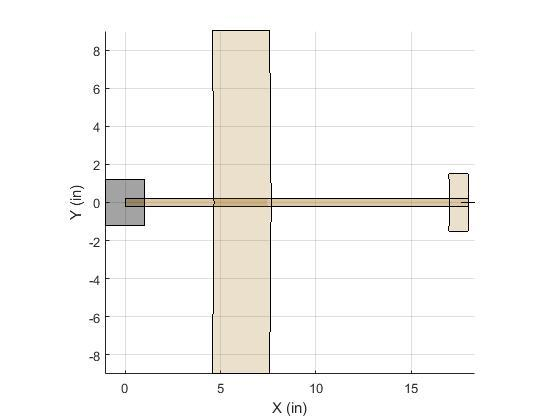

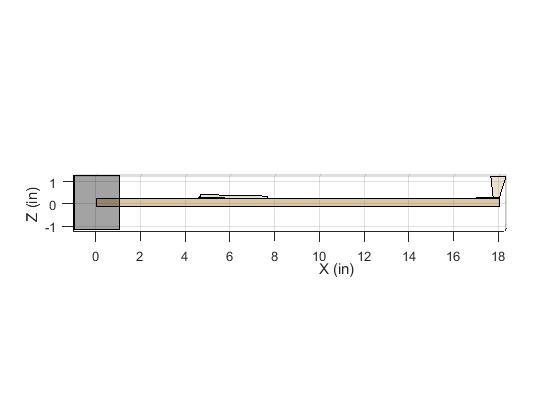

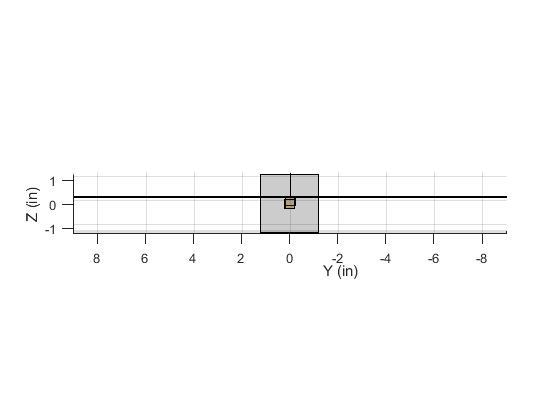

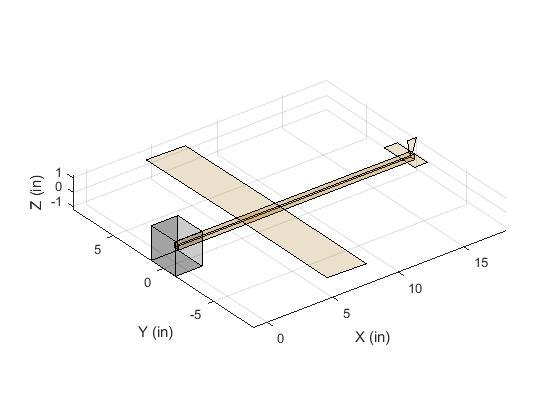

The INPUTS result is inserted into MA433_Glider_Project_Optimization.xlsx and the outputs from "% Data for AC+U1:X43_Data3 for Project 1" section are pasted into AC_Data3.m file as a case.

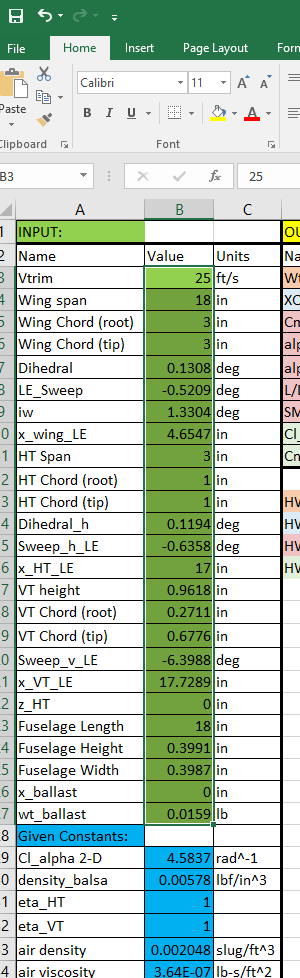

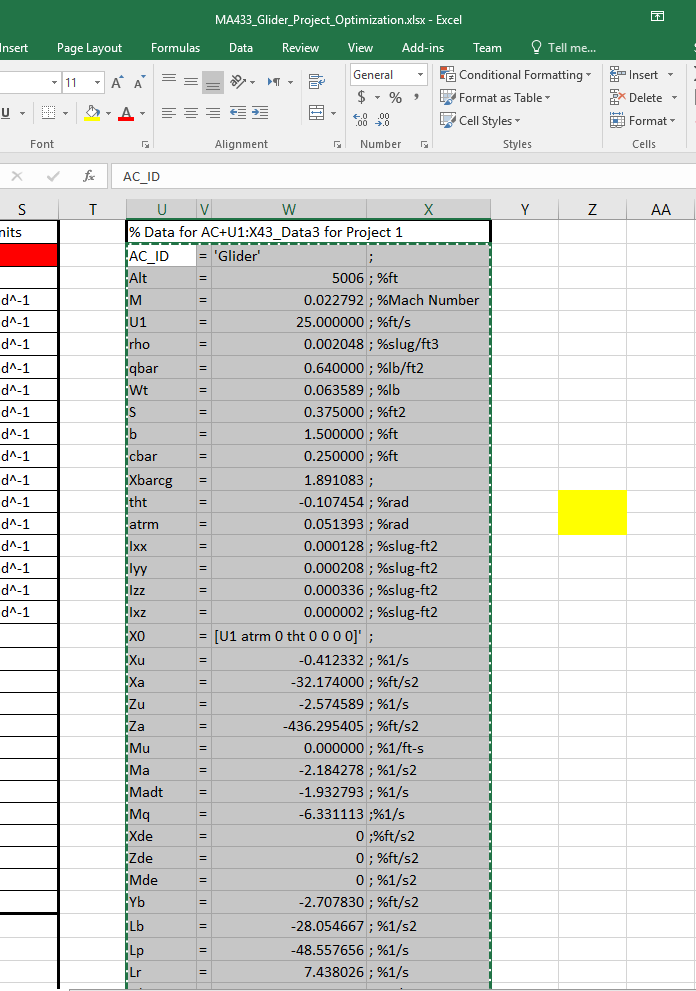

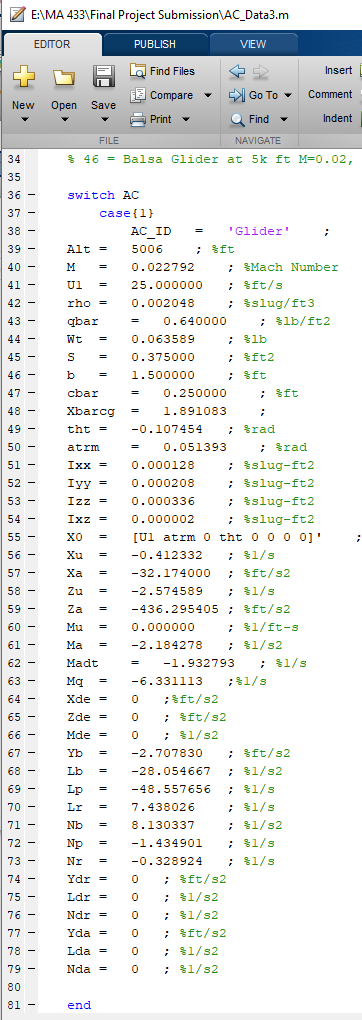

After doing so, the SIMULINK file Glider_Sim_2015b.slx is used.

Currently, the case number is number 1 as shown in the image attached above.

So in the Glider_Sim_2015b.slx file,

Model Properties > InitFcn

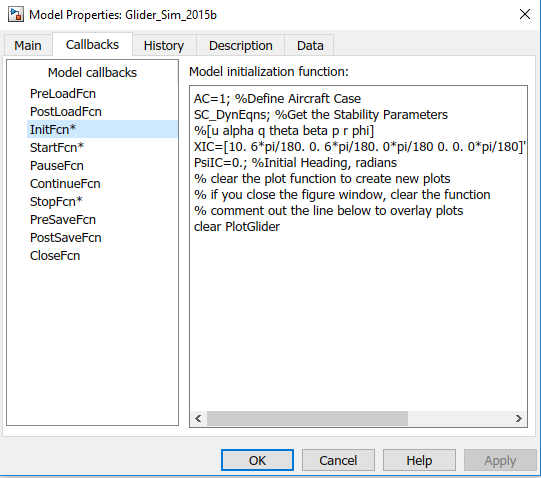

the case number is changed to 1 as AC = 1.

Small perturbation approach has to be used to linearize the equations of motion of the glider.

[u alpha q theta beta p r phi]' = [10. 6*pi/180. 0. 6*pi/180. 0*pi/180 0. 0. 0*pi/180]', which is the small perturbation values used in AE 413 Glider Project.

Then, the Simulink file Glider_Sim_2015b.slx is run.

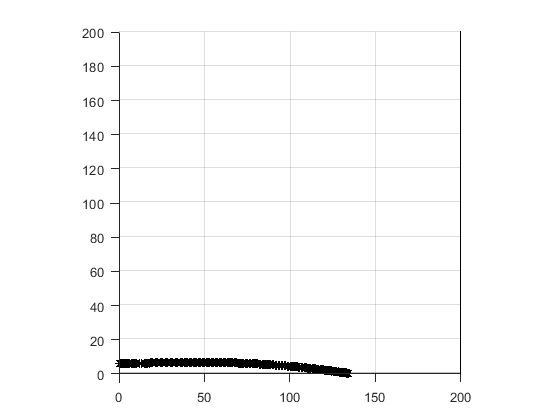

The glider glided about 134 ft and it was statically stable.

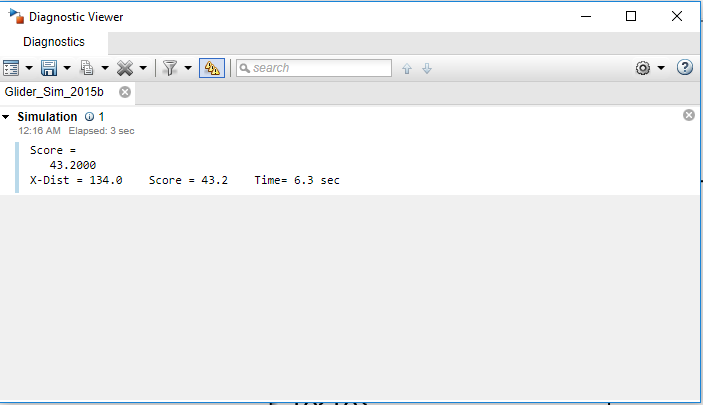

## Discussion and Recommendation

The objective of the Glider Project is to manufacture a balsa wood glider that is statically stable in all three axis and glides range of at most 100 ft. The objective of Optimization Project which is extension of Glider Project of AE 413 is to simulate an optimal glider which satisfies all requirements of static stability and range of 100 ft. Since the glider produced with this MATLAB file satisfied all requirements, the optimal glider is found.

For this optimization project, only simulation with SIMULINK is done, so actual flight test with balsa wood glider manufactured with the inputs found would be recommended.

For this optimization project, same values of small perturbation $[u, \alpha, q, \theta, \beta, p, r, \phi]$ used in AE 413 Glider Project are also used, so finding better small perturbations of $[u, \alpha, q, \theta, \beta, p, r, \phi]$, which gives more optimal, would also be recommended.

## Conclusion

The local optimal solution is found using the method of optimization learned in MA 433/AE 436 Introduction to Optimization.

This project is a good example of how optimization with linear and Nonlinear, equality and inequality constraints can be used in aerospace application.